# 绘制频率响应的bode图

正弦输入$u=\mathrm{Acos}\left(\mathrm{wt}\right)$的系统响应$y\left(t\right)=\mathrm{AMcos}\left(\mathrm{wt}+\varphi \right)$,$\varphi$,phi

传递函数：$H\left(s\right)=\frac{1}{s+k}$

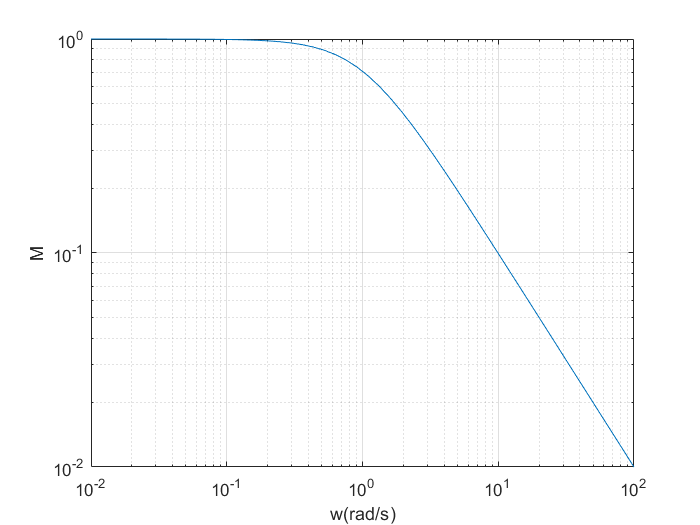

k=1;
tf=('s');   %定义拉普拉斯变量
sysH=1/(s+k); %传递函数
w=logspace(-2,2);  %设置频率范围
[mag,phase]=bode(sysH,w);  %求解频率响应（bode图），其中mag是得到的频率的幅值响应结果，phase是频率的相位响应结果
loglog(w,squeeze(mag));  %绘制幅值频率响应的对数图，loglog就是x和y轴都是用的对数刻度
xlabel('w(rad/s)');
ylabel('M');
grid on;

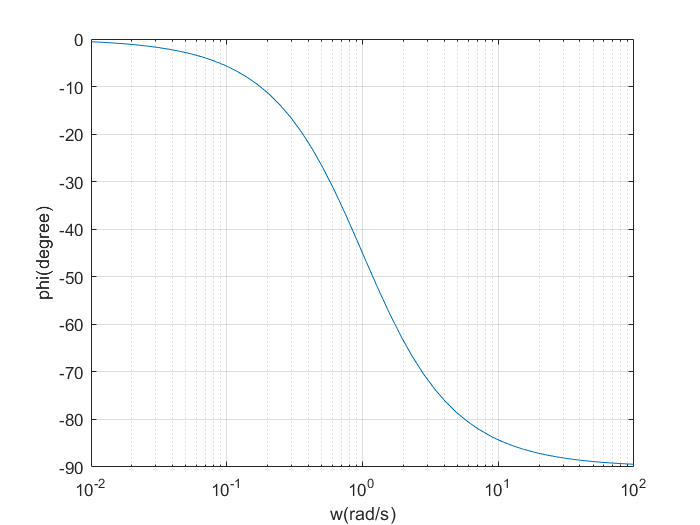

semilogx(w,squeeze(phase)); %绘制幅相位频率响应的对数图，semilogx就是x是对数，y轴是正常的刻度
xlabel('w(rad/s)');
ylabel('phi(degree)');
grid on;